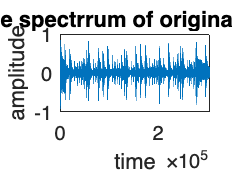

close all;
clear y Fs;

% load sample
sample = './samples/input/amenbreak.wav';

[x,Fs] = audioread(sample);
x = sum(x,2)/2; % set it mono
len_x = length(x); % set sample length

% plot amplitude spectrum of original sample
plot(x);
xlabel("time");
ylabel("amplitude");
title("amplitude spectrrum of original sample x(t)");

% definition of filter
filterIn = x;
octFiltBank = octaveFilterBank('SampleRate', Fs, FrequencyRange=[18 22000]);

% visualize filters magnitude response
fvt = fvtool(octFiltBank,"NFFT",2^16);
set(fvt,FrequencyScale="log");
zoom(fvt,[.01 24 -20 1]);

% center freq. of each filter
fc = getCenterFrequencies(octFiltBank);
% cf = string(size(fc));
cf = size(fc);
for ii = find(fc<1000)
    cf(ii) = round(fc(ii));
    % cf(ii) = sprintf("%.0f Hz",round(fc(ii),2,"significant"));
end
for ii = find(fc>=1000)
    cf(ii) = round(fc(ii)/1000);
    % cf(ii) = sprintf("%.1f kHz",fc(ii)/1000);
end
disp(fc); % center freq. of each filter

   1.0e+04 *

    0.0032    0.0063    0.0126    0.0251    0.0501    0.1000    0.1995    0.3981    0.7943    1.5849



% filtering
filterOut = octFiltBank(filterIn);
[N, numFilters, numChannels] = size(filterOut);

disp(N);

      306013



disp(numFilters);

    10



disp(numChannels);

     1



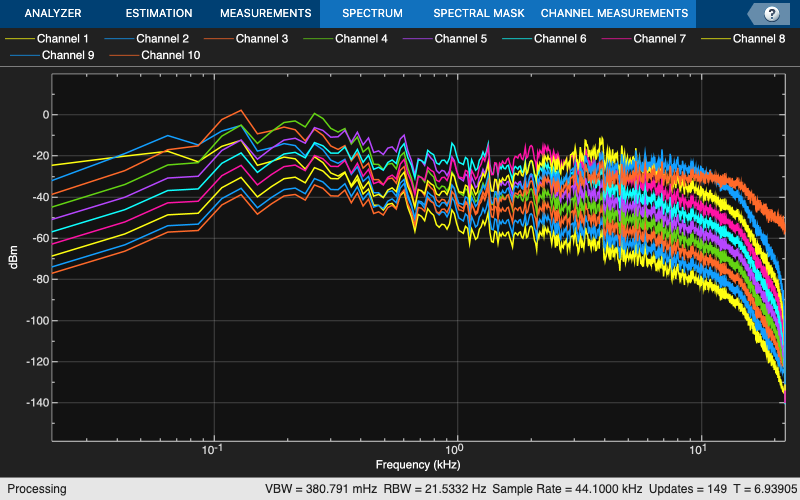


% spectrum analizer
sa = spectrumAnalyzer(SampleRate=Fs, PlotAsTwoSidedSpectrum=false, FrequencyScale="log");
sa(filterOut);


% conpensate group delays
groupDelay = round(getGroupDelays(octFiltBank)); % round for simplicity
filterPadded = [filterOut;zeros(max(groupDelay), numFilters, numChannels)];
for i = 1 : numFilters
    filterOut(:,i,:) = filterPadded(groupDelay(i)+1:N+groupDelay(i), i, :);
end


% export audio of each channels
for i = 1 : numFilters
    audiowrite('./samples/output/filterOut' + string(i) + '.wav', filterOut(:,i,:), Fs);
end

% for debag
test = filterOut(:,5,:);

% set the parameters for SDF
speedOfSound = 300;
distance = 300; % enter distance

initialDelay = round(distance * Fs / speedOfSound); % convert initial delay from (seconds) to (samples)
delaySamples = round(distance * Fs / 4000); % the sample differece of delayes between each channels
disp(initialDelay);

       44100



disp(delaySamples);

        3308




delayType = "linear"; % select delay curve type

% add delay to each channels according to user-setting parameters
% the highest freq. delayes most
for i = 1 : numFilters
    delayedColumn = [zeros(initialDelay + delaySamples*(i-1),1) ; filterOut(:,i,:); zeros(initialDelay + delaySamples*(numFilters-i),1)]; % insert zeros at both begining and end
    if i == 1
        delayOut = delayedColumn;
    else
        delayOut = [delayOut delayedColumn];
    end
end

% export audio of each channels
for i = 1 : numFilters
    audiowrite('./samples/output' + string(i) + '.wav', delayOut(:,i,:), Fs);
end

% reconstruct original signal (synthesis)
reconstructedAudio = squeeze(sum(delayOut, 2));
reconstructedAudio = reconstructedAudio/max(abs(reconstructedAudio(:))); % normalization
audiowrite('./samples/output/SDF_reconstruct_dist' + string(distance) + '.wav', reconstructedAudio, Fs); % notice: the output siganl is monoral

function p = delayTypePoint(i, delayType)
    if delayType == linear
        p = i;
    end
end